**The cart and pole system**

Consider the cart-and-pole system here depicted:

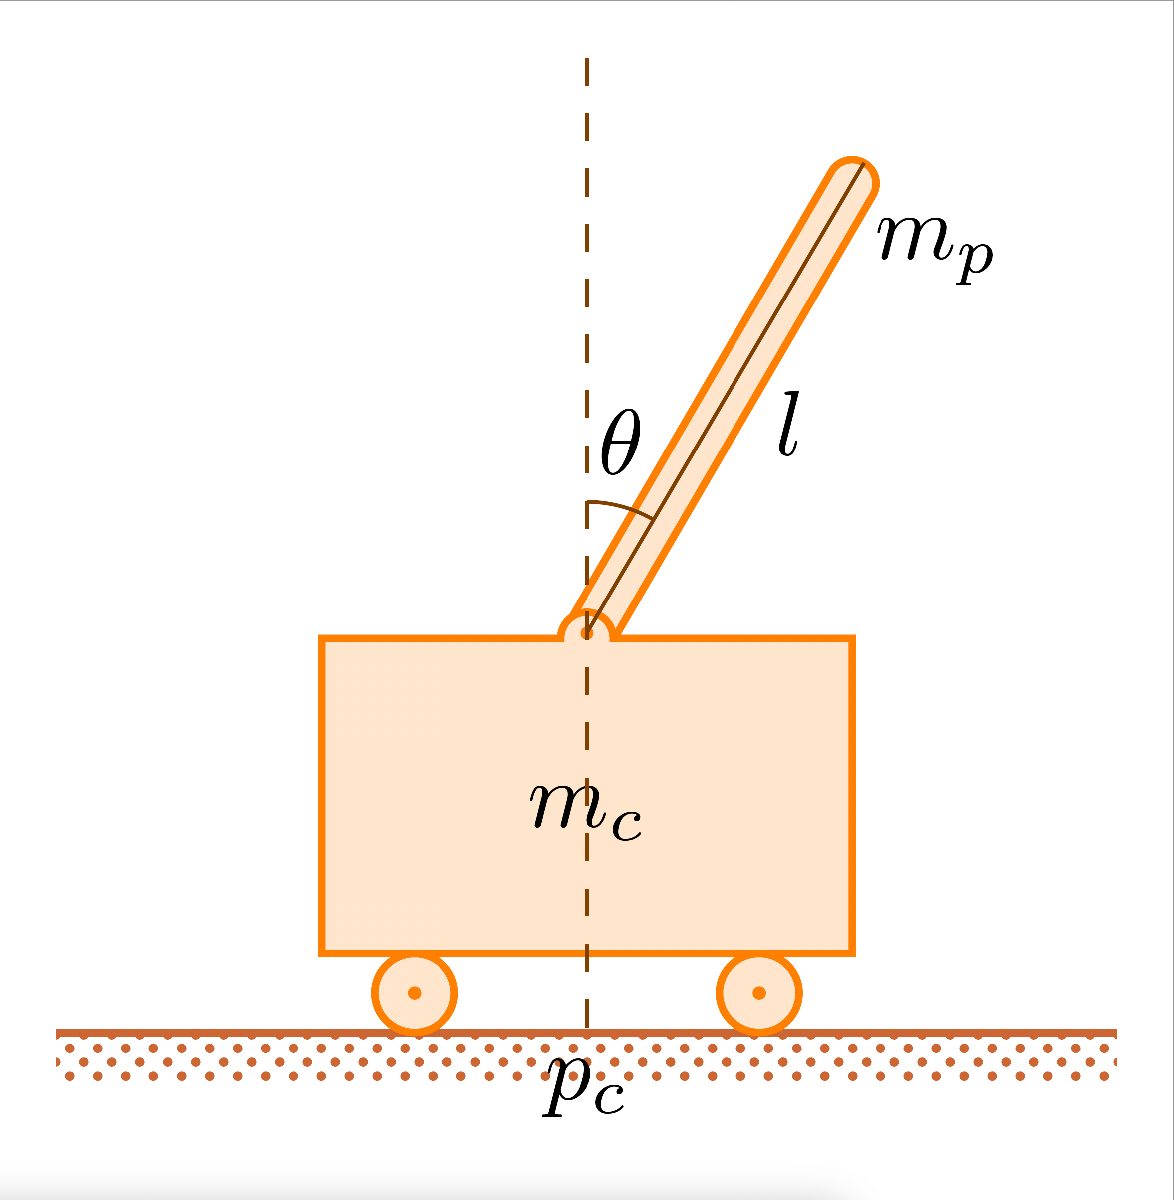

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient, and $F:|F|\leq 10\,\text{N}$ is the force applied to cart's center of mass.

1. Clearly define the state vector $x$ and the control input vector $u$. Define also the domains to which they belong, $X$ and $U$respectively.

% Answer: (Arguing the answer)

The state vector $x$ is:

                        
$$x = \left( \begin{array}{ccc}
                cp \\
                \dot cp \\
                \theta \\
                \dot \theta
\end{array} \right)
=
\left( \begin{array}{ccc}
                  x_1 \\
                  x_2 \\
                  x_3 \\
                  x_4
\end{array} \right)
$$


- $cp$ is the cart position 

- $\dot cp$ is the speed of the cart

- $\theta$ is the angular position of the pole

- $\dot \theta$ is the angular speed of the pole

Note that $\theta = 0$ is when the pole is up.

The control input $u$ is the force applied to the cart:

                            
$$u = F$$


All the variables $x_1,... , x_4,u \in \mathbb{R}$, respectively $X = \mathbb{R}$ and $U = \mathbb{R}$ with the constraint that $u < 10 \ N$

2. Compute the equilibrium state $$\bar{x}$$ when the control input $$\bar{u}$$ is set equal to $$0$$.

% Answer: (Arguing the answer)
close all
clear all
clc

g = 9.8;
mc = 1;
mp = 0.1;
l = 0.5;
mu_p = 2e-6;

syms x1 x2 x3 x4;
assume(x3 > -pi/2 | x3 < pi/2);
F = 0;

d_x3 = x4;
d_x4 = (g*sin(x3)+ cos(x3)*((-F-mp*l*(x4^2)*sin(x3))/(mc+mp))-((mu_p*x4)/(mp*l))) / (l*((4/3)-((mp*(cos(x3)^2))/(mc+mp))));

d_x1 = x2;
d_x2 = (F+mp*l*((x4^2)*sin(x3)-d_x4*cos(x3)))/(mc+mp);

The following code will solve the system of equation with the constraint that the angular position $\theta$ will stay between $-\pi/2$ and $\pi/2$.

This constraint has been done because we want to compute only the unstable equilibrium point, that is the one wich is relevant for the simulation and the following tasks.

equil_p = solve([d_x1 d_x2 d_x3 d_x4], [x1 x2 x3 x4]);
equil_p.x1

$$ans = 0$$

equil_p.x2

$$ans = 0$$

equil_p.x3

$$ans = 0$$

equil_p.x4

$$ans = 0$$

The data we want to observe is **equil_p.x3 = 0** wich is the equivalent of $\theta = 0 \ rad$

The following code will simulate the system starting from a random initial state for the angular position of the pole, wich is the only relevant data we want to observe.

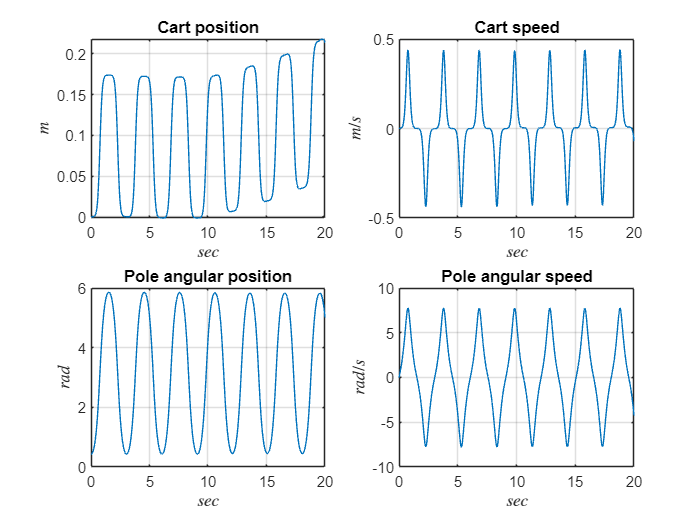

tspan = 0:0.01:20;
theta_0 = rand(1,1);
x0 = [0 0 theta_0 0];

[t,x] = ode45(@(t,x)cart_pend(t, x, g, mp, mc, l, mu_p, F), tspan, x0);
[t_stab,x_stab] = ode45(@(t,x)cart_pend(t, x, g, mp, mc, l, mu_p, F), tspan, [0 0 0 0]);

subplot(2,2,1);
plot(t, x(:,1));
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
title("Cart position");

subplot(2,2,2);
plot(t, x(:,2));
grid on
xlabel("$sec$", Interpreter="latex");
ylabel("$m/s$", Rotation=90, Interpreter="latex");
title("Cart speed");

subplot(2,2,3);
plot(t, x(:,3));
grid on;
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
title("Pole angular position");

subplot(2,2,4);
plot(t, x(:,4));
grid on
xlabel("$sec$", Interpreter="latex");
ylabel("$rad/s$", Rotation=90, Interpreter="latex");
title("Pole angular speed");

As expected, we can see that if the initial condition ar different from the equilibrium point computed before, the pole will fall and continue rotating

Here there is the plot of the angular position of the simulation when the initial condition are equal to the equilibium point.

We can easly see that the pole is staying up.

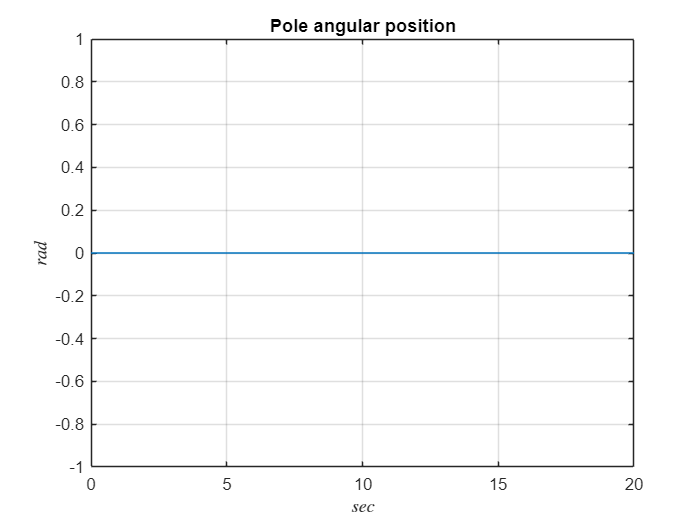

close all;
plot(t_stab, x_stab(:,3));
grid on;
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
title("Pole angular position");

3. Given the sequence of control inputs $ $$\left[u^{(0)},\,u^{(1)},\cdots,u^{(1001)}\right]$$$ simulate the behaviour of the non linear system $$(*)$$ 

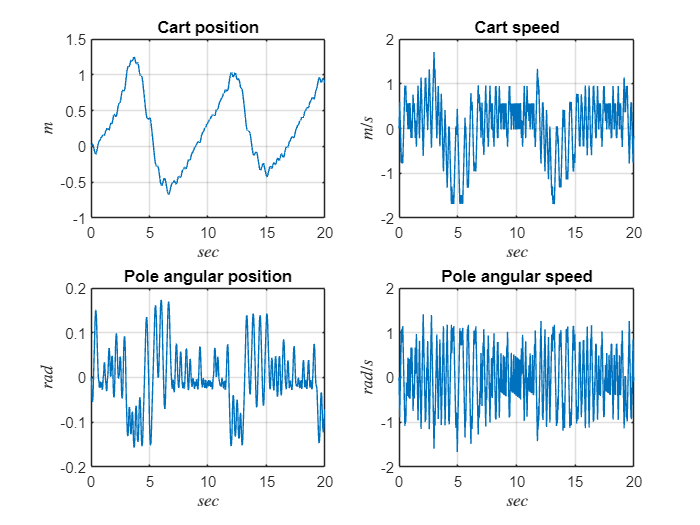

% Answer: (Provide the code, an animation of the system the plots of the state evolution)
load U;
x0 = [0 0 0 0];
Ts = 0;
for i=1:1:999
    Ts = [Ts Ts(end)+0.02];
end
j1 = 1;

for i=1:1:999

    [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, U(i)), [Ts(i) Ts(i+1)], x0);
   
    sz = size(x);
    
    j2 = j1 + sz(1)-1;

    xout([j1:j2], :) = x;
    tout([j1:j2], :) = t;

    j1 = j2;

    x0 = x(end, :);
end


close all
subplot(2,2,1);
plot(tout, xout(:,1));
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
title("Cart position");

subplot(2,2,2);
plot(tout, xout(:,2));
grid on
xlabel("$sec$", Interpreter="latex");
ylabel("$m/s$", Rotation=90, Interpreter="latex");
title("Cart speed");

subplot(2,2,3);
plot(tout, xout(:,3));
grid on;
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
title("Pole angular position");

subplot(2,2,4);
plot(tout, xout(:,4));
grid on
xlabel("$sec$", Interpreter="latex");
ylabel("$rad/s$", Rotation=90, Interpreter="latex");
title("Pole angular speed");

4. Given the non linear system $(\ast )$ linearize it around the equilibrium point computed in the point 2 and simulate the behaviour of the linear systems given the same sequence of control inputs of point 3.

% Answer: (Provide the code, an animation of the system the plots of the state evolution)
syms x1 x2 x3 x4 F;
d_x3 = x4;
d_x4 = (g*sin(x3)+ cos(x3)*((-F-mp*l*(x4^2)*sin(x3))/(mc+mp))-((mu_p*x4)/(mp*l))) / (l*((4/3)-((mp*(cos(x3)^2))/(mc+mp))));

d_x1 = x2;
d_x2 = (F+mp*l*((x4^2)*sin(x3)-d_x4*cos(x3)))/(mc+mp);

a = jacobian([d_x1 d_x2 d_x3 d_x4], [x1 x2 x3 x4]);
A_sym = subs(a, [x1 x2 x3 x4], [0 0 0 0]);
Avpa = vpa(A_sym, 4)

$$Avpa = \left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ 0 & 0 & -0.7171 & 2.927e-6\\ 0 & 0 & 0 & 1.0\\ 0 & 0 & 15.78 & -6.439e-5 \end{array}\right)$$


b = jacobian([d_x1 d_x2 d_x3 d_x4], F);
B_sym = subs(b, [F x3], [0 0]);
Bvpa = vpa(B_sym, 4)

$$Bvpa = \left(\begin{array}{c} 0\\ 0.9756\\ 0\\ -1.463 \end{array}\right)$$

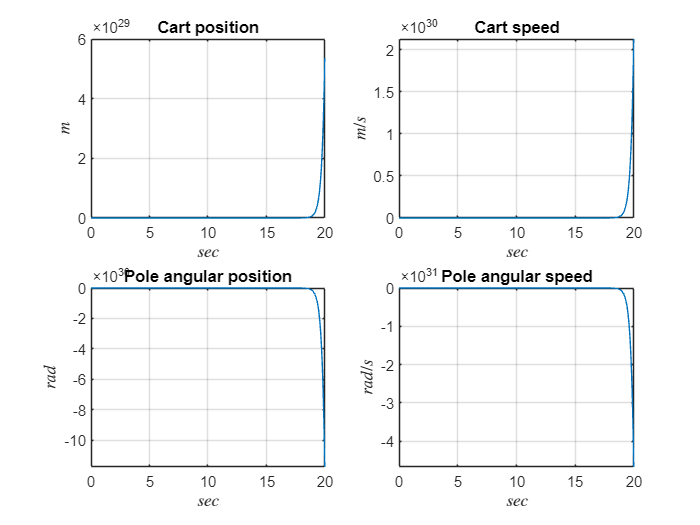

A = double(A_sym);
B = double(B_sym);
C = eye(4);
D = zeros(4,1);
sys_C = ss(A, B, C, D);
sys_D = c2d(sys_C, 0.02);

X_lin = lsim(sys_D, U, Ts, [0 0 0 0]);


close all;
subplot(2,2,1);
plot(Ts, X_lin(:,1));
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
title("Cart position");

subplot(2,2,2);
plot(Ts, X_lin(:,2));
grid on
xlabel("$sec$", Interpreter="latex");
ylabel("$m/s$", Rotation=90, Interpreter="latex");
title("Cart speed");

subplot(2,2,3);
plot(Ts, X_lin(:,3));
grid on;
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
title("Pole angular position");

subplot(2,2,4);
plot(Ts, X_lin(:,4));
grid on
xlabel("$sec$", Interpreter="latex");
ylabel("$rad/s$", Rotation=90, Interpreter="latex");
title("Pole angular speed");

5. Comment the results obtained in point 3 and 4. Do you observe any difference?